# Señales y sistemas

## Handles vs Symbolic

syms t

%Variable simbólica
y_symb=cos(t)

$$y\_symb = \cos\left(t\right)$$


%Function handle
y_fh= @(t) cos(t)

y_fh = function_handle with value:
    @(t)cos(t)


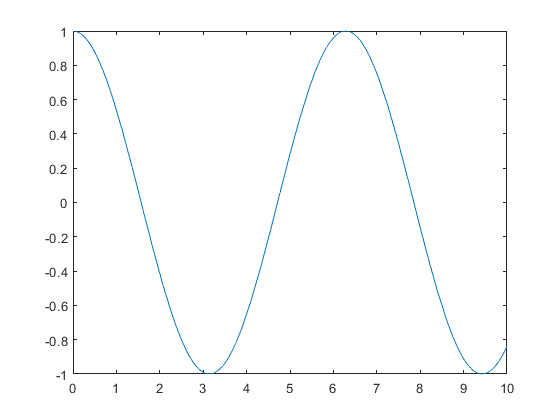


%f plot es para funciones simbólicas y también para "fuction handles"
figure
fplot(y_symb,[0 10])


figure
fplot(y_fh,[0 10])


%Diferencia entre variables simbólicas y function handles
y_fh([5 8 10]) %Se evaluan directamente

ans =     0.2837   -0.1455   -0.8391


%y_symb([5 8 10]) %ERROR: NO se evaluan directamente
subs(y_symb,t,[5 8 10])

$$ans = \left(\begin{array}{ccc} \cos\left(5\right) & \cos\left(8\right) & \cos\left(10\right) \end{array}\right)$$


%Se puede hacer algebra con variables simbolicas
y_3=y_symb+sin(t)+exp(-t)

$$y\_3 = {\mathrm{e}}^{-t}+\cos\left(t\right)+\sin\left(t\right)$$

diff(y_3)

$$ans = \cos\left(t\right)-{\mathrm{e}}^{-t}-\sin\left(t\right)$$

int(y_3,[0 1])

$$ans = \sin\left(1\right)-{\mathrm{e}}^{-1}-\cos\left(1\right)+2$$

int(y_3,t)

$$ans = -{\mathrm{e}}^{-t}-\sqrt{2}\,\cos\left(t+\frac{\pi }{4}\right)$$

%y_fh+y_fh %ERROR: no se pueden hacer operaciones con fucntion handles
y_3_fh=matlabFunction(y_3)

y_3_fh = function_handle with value:
    @(t)exp(-t)+cos(t)+sin(t)


y_3_fh([5 8 10])

ans =    -0.6685    0.8442   -1.3830


Funciones Continuas vs Discretas

t_disc=0:10

t_disc =      0     1     2     3     4     5     6     7     8     9    10


t_disc=0:10;

y_disc=y_fh(t_disc)

y_disc =     1.0000    0.5403   -0.4161   -0.9900   -0.6536    0.2837    0.9602    0.7539   -0.1455   -0.9111   -0.8391


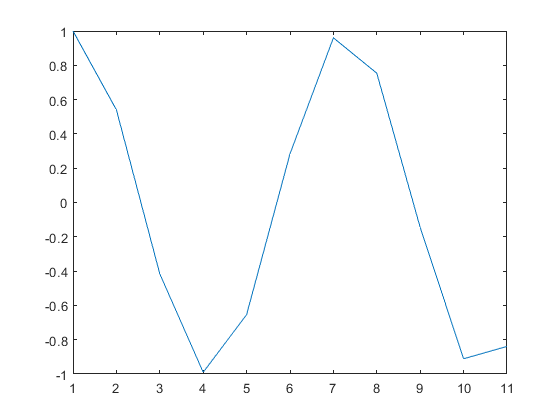


figure
%plot es para muestras/vectores
plot(y_disc)

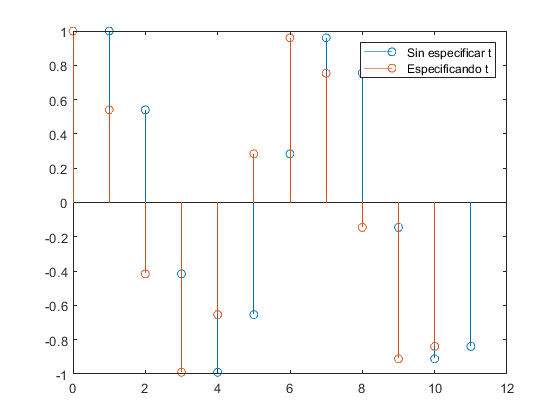


figure
stem(y_disc)
hold on
%figure
%stem es para muestras/vectores
stem(t_disc,y_disc)
hold off
legend("Sin especificar t","Especificando t")


t_disc=0:0.1:10

t_disc =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y_disc=y_fh(t_disc)

y_disc =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


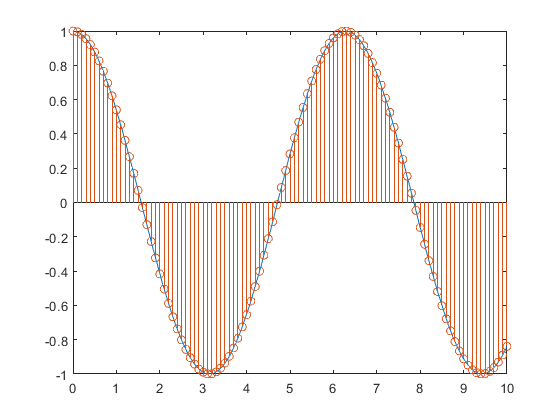


figure
fplot(y_fh,[0 10])
hold on
stem(t_disc,y_disc)
hold off

### Ejercicio 1


x=3*exp(0.4*t)

$$x = 3\,{\mathrm{e}}^{\frac{2\,t}{5}}$$

y=2*exp(-0.9*t)

$$y = 2\,{\mathrm{e}}^{-\frac{9\,t}{10}}$$

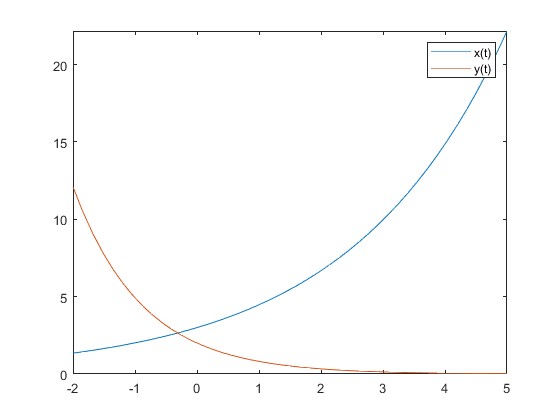

figure
fplot(x,[-2,5])
hold on
fplot(y,[-2,5])
legend("x(t)","y(t)")
hold off

### Ejercicio 2


t_1=0:0.1:19

t_1 =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


x_t=cos(t_1)+sin(3*t_1)

x_t =     1.0000    1.2905    1.5447    1.7387    1.8531    1.8751    1.7992    1.6281    1.3722    1.0490    0.6814    0.2959   -0.0802   -0.4203   -0.7016   -0.9068   -1.0254   -1.0547   -1.0000   -0.8740   -0.6956   -0.4880   -0.2770   -0.0878    0.0563    0.1369    0.1417    0.0658   -0.0876   -0.3080   -0.5779   -0.8747   -1.1726   -1.4450   -1.6667   -1.8162   -1.8777   -1.8427   -1.7103   -1.4879   -1.1902   -0.8381   -0.4566   -0.0733    0.2847    0.5930    0.8315    0.9869    1.0532    1.0323


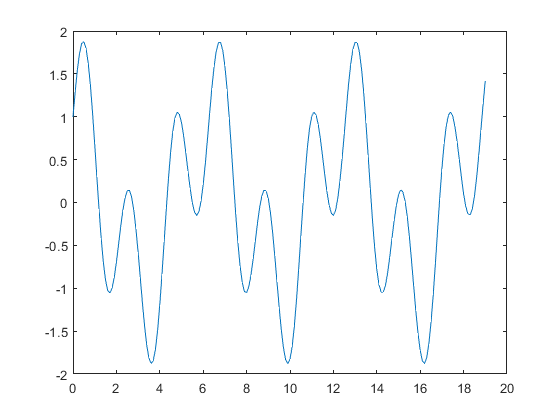

plot(t_1,x_t)

### Formas de onda básicas

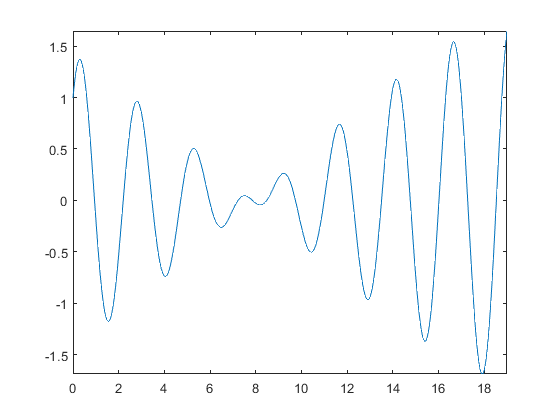

syms t
a=2.6;
b=2.4;
t0=25.5;
tf=91.3;
x(t)=cos(a*t)+sin(b*t);

figure
fplot(x,[0 19])

### Ejercicio 3

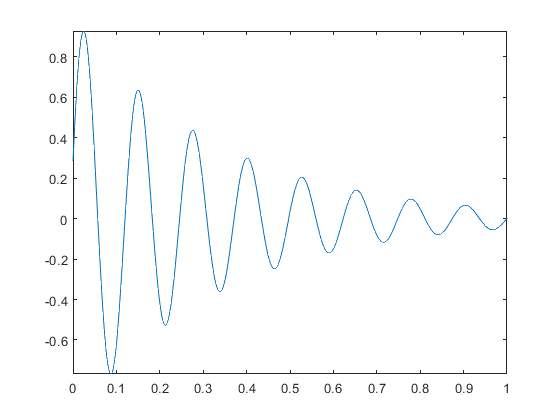

syms t
t0=0;
tf=1;
theta=5;
omega=50;
C=1;
r=-3;
figure
x_1=C*exp(r*t)*cos(omega*t+theta);
fplot(x_1,[t0 tf])

### Gráfica de la función seno

t=0:0.01:100;
x_t=sin(t)

x_t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0699    0.0799    0.0899    0.0998    0.1098    0.1197    0.1296    0.1395    0.1494    0.1593    0.1692    0.1790    0.1889    0.1987    0.2085    0.2182    0.2280    0.2377    0.2474    0.2571    0.2667    0.2764    0.2860    0.2955    0.3051    0.3146    0.3240    0.3335    0.3429    0.3523    0.3616    0.3709    0.3802    0.3894    0.3986    0.4078    0.4169    0.4259    0.4350    0.4439    0.4529    0.4618    0.4706


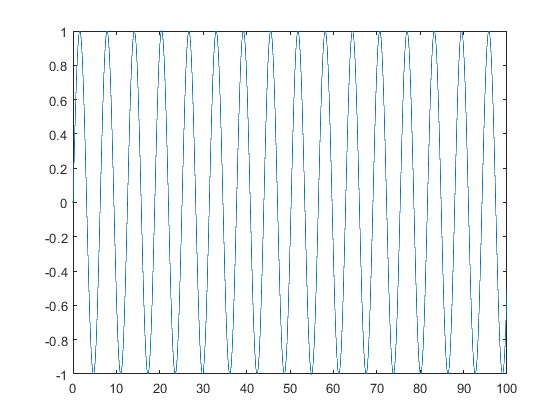


plot(t,x_t)

### Gráfica de la función coseno

t=0:0.01:100;
x_t=cos(t)

x_t =     1.0000    1.0000    0.9998    0.9996    0.9992    0.9988    0.9982    0.9976    0.9968    0.9960    0.9950    0.9940    0.9928    0.9916    0.9902    0.9888    0.9872    0.9856    0.9838    0.9820    0.9801    0.9780    0.9759    0.9737    0.9713    0.9689    0.9664    0.9638    0.9611    0.9582    0.9553    0.9523    0.9492    0.9460    0.9428    0.9394    0.9359    0.9323    0.9287    0.9249    0.9211    0.9171    0.9131    0.9090    0.9048    0.9004    0.8961    0.8916    0.8870    0.8823


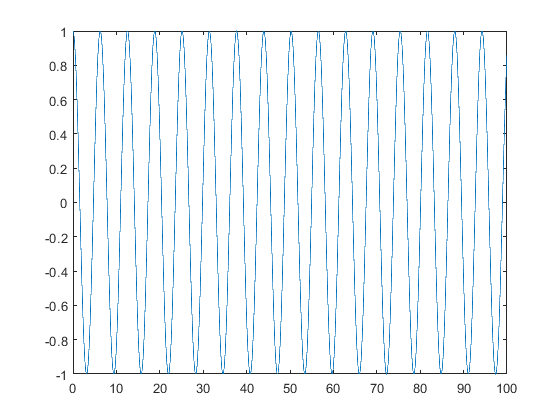


plot(t,x_t)